# Tune PI Controller Using Reinforcement Learning

This example shows how to tune the two gains of a PI controller using the twin-delayed deep deterministic policy gradient (TD3) reinforcement learning algorithm. The performance of the tuned controller is compared with that of a controller tuned using the **Control System Tuner** app. Using the **Control System Tuner** app to tune controllers in Simulink® requires Simulink Control Design™ software.

For relatively simple control tasks with a small number of tunable parameters, model-based tuning techniques can get good results with a faster tuning process compared to model-free RL-based methods. However, RL methods can be more suitable for highly nonlinear systems or adaptive controller tuning. To facilitate the controller comparison, both tuning methods use a linear quadratic Gaussian (LQG) objective function. For an example that uses a DDPG agent to implement an LQR controller, see [Train DDPG Agent to Control Double Integrator System](docid:rl_ug#mw_0b71212e-521a-4a57-bde7-5dde0c1e0c90).

This example uses a reinforcement learning (RL) agent to compute the gains for a PI controller. For an example that replaces the PI controller with a neural network controller, see [Create Simulink Environment and Train Agent](docid:rl_ug#mw_873bd3fc-b713-4e71-b776-9758762d592c).

## Environment Model

The environment model for this example is a water tank model. The goal of this control system is to maintain the level of water in a tank to match a reference value.

open_system('watertankLQG')

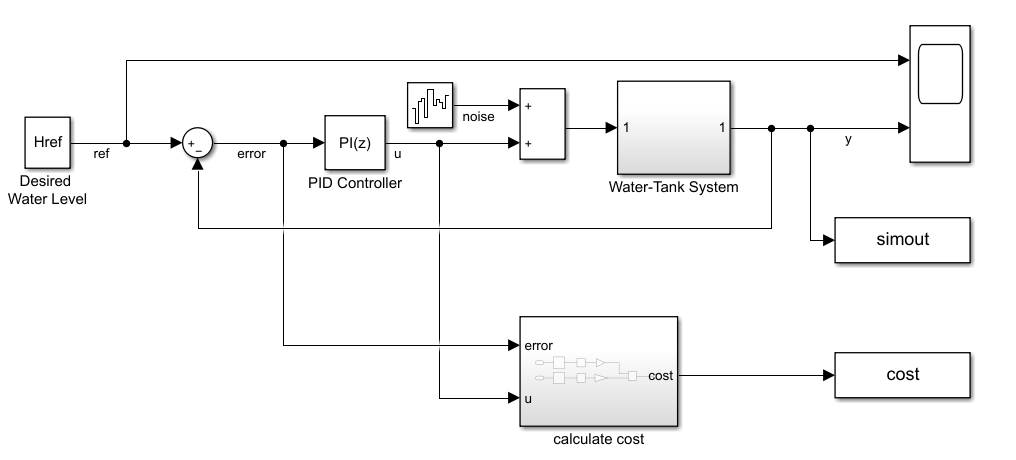

The model includes process noise with variance $E\left(n^2 \left(t\right)\right)=1$.

To maintain the water level while minimizing control effort `u`, the controllers in this example use the following LQG criterion.


$$J=\lim_{T\Rightarrow \infty } E\left(\frac{1}{T}\int_0^T \left({\left(\textrm{Href}-y\left(t\right)\right)}^2 +0\ldotp 01u^2 \left(t\right)\right)\textrm{dt}\right)$$


To simulate the controller in this model, you must specify the simulation time `Tf` and the controller sample time `Ts` in seconds.

Ts = 0.1;
Tf = 10;

For more information about the water tank model, see [watertank Simulink Model](docid:slcontrol_gs#bsp4o3g). 

## Tune PI Controller Using Control System Tuner

To tune a controller in Simulink using **Control System Tuner**, you must specify the controller block as a tuned block and define the goals for the tuning process. For more information on using **Control System Tuner**, see [Tune a Control System Using Control System Tuner](docid:slcontrol_ug#bugkabi).

For this example, open the saved session `ControlSystemTunerSession.mat` using **Control System Tuner**. This session specifies the PID Controller block in the `watertankLQG` model as a tuned block and contains an LQG tuning goal.

To tune the controller, on the **Tuning** tab, click** Tune**.

The tuned proportional and integral gains are approximately 9.8 and 1e-6, respectively.

Kp_CST = 9.80199999804512;
Ki_CST = 1.00019996230706e-06;

## Create Environment for Training Agent

To define the model for training the RL agent, modify the water tank model using the following steps.

- Delete the PID Controller.

- Insert an RL Agent block.

- Create the observation vector ${\left\lbrack \begin{array}{ccc}
\int e\;\textrm{dt} & e & 
\end{array}\right\rbrack }^{T\;}$ where $e=\textrm{Href}-h$,  $h$ is the height of the water in the tank, and $\textrm{Href}$ is the reference water height. Connect the observation signal to the RL Agent block.

- Define the reward function for the RL agent as the **negative** of the LQG cost , that is, $\textrm{Reward}=-\left({\left(\textrm{Href}-h\left(t\right)\right)}^2 +0\ldotp 01u^2 \left(t\right)\right)$. The RL agent maximizes this reward, thus minimizing the LQG cost.

The resulting model is `rlwatertankPIDTune.slx`.

mdl = 'rlwatertankPIDTune';
open_system(mdl)

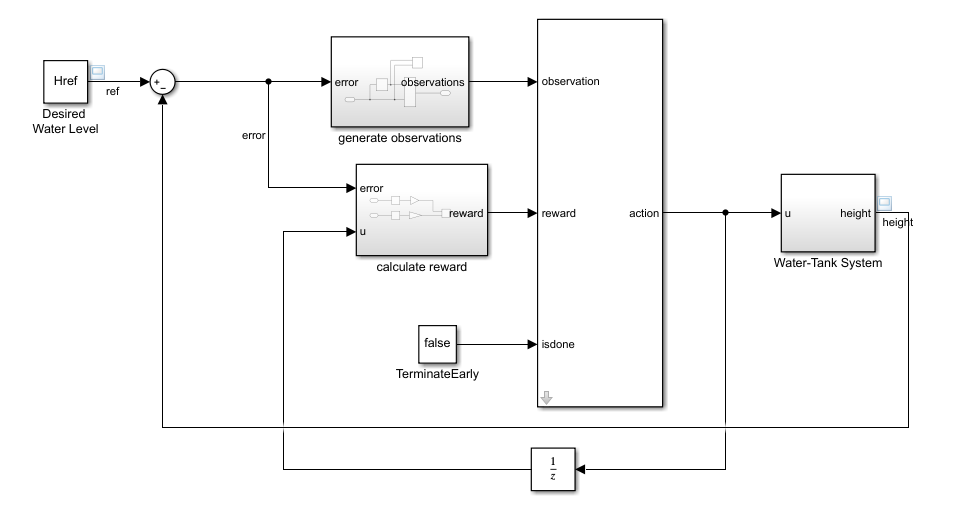

Create the environment interface object. To do so, use the `localCreatePIDEnv` function defined at the end of this example.

[env,obsInfo,actInfo] = localCreatePIDEnv(mdl);

Extract the observation and action dimensions for this environment. Use `prod(obsInfo.Dimension)` and `prod(actInfo.Dimension)` to return the number of dimensions of the observation and action spaces, respectively, regardless of whether they are arranged as row vectors, column vectors, or matrices.

numObs = prod(obsInfo.Dimension);
numAct = prod(actInfo.Dimension);

Fix the random generator seed for reproducibility.

rng(0)

### **Create TD3 Agent**

To create the actor, first create a deep neural network with the observation input and the action output. For more information, see [`rlContinuousDeterministicActor`](docid:rl_ref#mw_c2909424-90f4-4a52-803b-73310483e6c3).

You can model a PI controller as a neural network with one fully-connected layer with error and error integral observations. 


$$u=\;\left\lbrack \begin{array}{ccc}
\int e\;\textrm{dt} & e & 
\end{array}\right\rbrack *{\left\lbrack \begin{array}{ccc}
K_i  & K_p  & 
\end{array}\right\rbrack }^{T\;}$$


Here:

- `u` is the output of the actor neural network.

- `Kp` and `Ki` are the absolute values of the neural network weights.

- $e=\textrm{Href}-h\left(t\right)$,  $h\left(t\right)$ is the height of the tank, and $\textrm{Href}$ is the reference height.

Gradient descent optimization can drive the weights to negative values. To avoid negative weights, replace normal `fullyConnectedLayer` with a `fullyConnectedPILayer`. This layer ensures that the weights are positive by implementing the function $Y=\textrm{abs}\left(\textrm{WEIGHTS}\right)*X$ and it is defined in the file `fullyConnectedPILayer.m` (which must be in the MATLAB search path or in the current folder when this agent is used). For more information on defining custom layers, see [Define Custom Deep Learning Layers](docid:nnet_ug#mw_6bb441da-736f-4131-af53-bfe9d11fc576).

initialGain = single([1e-3 2]);

actorNet = [
    featureInputLayer(numObs)
    fullyConnectedPILayer(initialGain,'ActOutLyr')
    ];

actorNet = dlnetwork(actorNet);


actor = rlContinuousDeterministicActor(actorNet,obsInfo,actInfo);

The agent in this example is a twin-delayed deep deterministic policy gradient (TD3) agent. TD3 agents rely on actor and critic approximator objects to learn the optimal policy. 

A TD3 agent approximates the long-term reward given observations and actions using two critic value-function representations. To create the critics, first create a deep neural network with two inputs, the observation and action, and one output. 

To create the critics, use the `localCreateCriticNetwork` function defined at the end of this example. Use the same network structure for both critic representations.

criticNet = localCreateCriticNetwork(numObs,numAct);

Create the critic objects using the specified neural network and the environment action and observation specifications. Pass as additional arguments also the names of the network layers to be connected with the observation and action channels.

critic1 = rlQValueFunction(dlnetwork(criticNet), ...
    obsInfo,actInfo,...
    ObservationInputNames='stateInLyr', ...
    ActionInputNames='actionInLyr');

critic2 = rlQValueFunction(dlnetwork(criticNet), ...
    obsInfo,actInfo,...
    ObservationInputNames='stateInLyr', ...
    ActionInputNames='actionInLyr');

critic = [critic1 critic2];

Specify training options for the actor and critic.

actorOpts = rlOptimizerOptions( ...
    LearnRate=1e-3, ...
    GradientThreshold=1);

criticOpts = rlOptimizerOptions( ...
    LearnRate=1e-3, ...
    GradientThreshold=1);

Specify the TD3 agent options using [`rlTD3AgentOptions`](docid:rl_ref#mw_372ffd1e-e1d2-453c-a691-cfef5da40ef8). Include the training options for the actor and critic.

- Set the agent to use the controller sample time `Ts`.

- Set the mini-batch size to `128` experience samples.

- Set the experience buffer length to `1e6`.

- Set the exploration model and target policy smoothing model to use Gaussian noise with variance of `0.1`.

agentOpts = rlTD3AgentOptions(...
    SampleTime=Ts,...
    MiniBatchSize=128, ...
    ExperienceBufferLength=1e6,...
    ActorOptimizerOptions=actorOpts,...
    CriticOptimizerOptions=criticOpts);

You can also set or modify the agent options using dot notation.

agentOpts.TargetPolicySmoothModel.StandardDeviation = sqrt(0.1);

Create the TD3 agent using the specified actor representation, critic representation, and agent options. For more information, see [`rlTD3Agent`](docid:rl_ref#mw_372ffd1e-e1d2-453c-a691-cfef5da40ef8).

agent = rlTD3Agent(actor,critic,agentOpts);

## Train Agent

To train the agent, first specify the following training options.

- Run each training for at most 1000 episodes, with each episode lasting at most 100 time steps.

- Display the training progress in the Episode Manager (set the `Plots` option) and disable the command-line display (set the `Verbose` option).

- Stop training when the agent receives an average cumulative reward greater than -355 over 100 consecutive episodes. At this point, the agent can control the level of water in the tank.

For more information, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

maxepisodes = 1000;
maxsteps = ceil(Tf/Ts);
trainOpts = rlTrainingOptions(...
    MaxEpisodes=maxepisodes, ...
    MaxStepsPerEpisode=maxsteps, ...
    ScoreAveragingWindowLength=100, ...
    Verbose=false, ...
    Plots="training-progress",...
    StopTrainingCriteria="AverageReward",...
    StopTrainingValue=-355);

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training this agent is a computationally intensive process that takes several minutes to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

doTraining = false;

if doTraining
    % Train the agent.
    trainingStats = train(agent,env,trainOpts);
else
    % Load pretrained agent for the example.
    load("WaterTankPIDtd3.mat","agent")
end

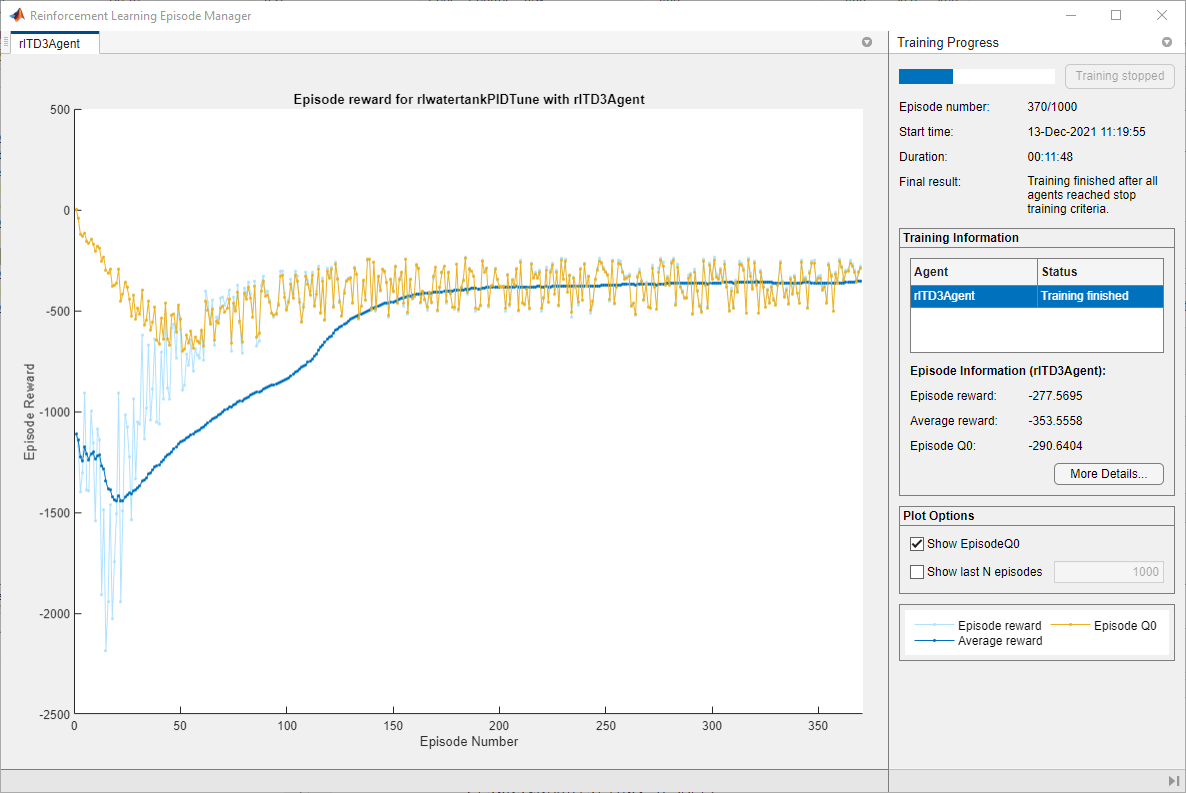

## Validate Trained Agent

Validate the learned agent against the model by simulation.

simOpts = rlSimulationOptions(MaxSteps=maxsteps);
experiences = sim(env,agent,simOpts);

The integral and proportional gains of the PI controller are the absolute weights of the actor representation. To obtain the weights, first extract the learnable parameters from the actor.

actor = getActor(agent);
parameters = getLearnableParameters(actor);

Obtain the controller gains.

Ki = abs(parameters{1}(1))

Ki = single
0.3958

Kp = abs(parameters{1}(2))

Kp = single
8.0822

Apply the gains obtained from the RL agent to the original PI controller block and run a step-response simulation.

mdlTest = 'watertankLQG';
open_system(mdlTest); 
set_param([mdlTest '/PID Controller'],'P',num2str(Kp))
set_param([mdlTest '/PID Controller'],'I',num2str(Ki))
sim(mdlTest)

Extract the step response information, LQG cost, and stability margin for the simulation. To compute the stability margin, use the `localStabilityAnalysis` function defined at the end of this example.

rlStep = simout;
rlCost = cost;
rlStabilityMargin = localStabilityAnalysis(mdlTest);

Apply the gains obtained using **Control System Tuner** to the original PI controller block and run a step-response simulation.

set_param([mdlTest '/PID Controller'],'P',num2str(Kp_CST))
set_param([mdlTest '/PID Controller'],'I',num2str(Ki_CST))
sim(mdlTest)
cstStep = simout;
cstCost = cost;
cstStabilityMargin = localStabilityAnalysis(mdlTest);

## Compare Controller Performance

Plot the step response for each system.

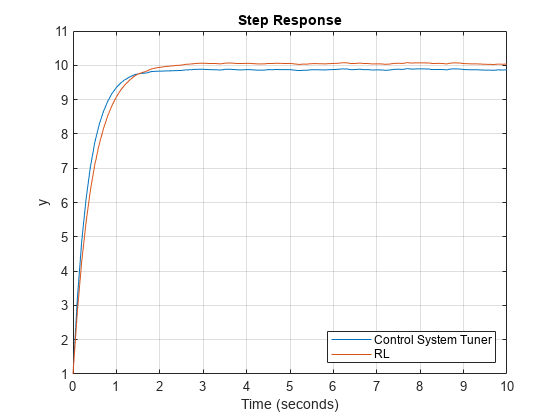

figure
plot(cstStep)
hold on
plot(rlStep)
grid on
legend('Control System Tuner','RL',Location="southeast")
title('Step Response')

Analyze the step response for both simulations.

rlStepInfo = stepinfo(rlStep.Data,rlStep.Time);
cstStepInfo = stepinfo(cstStep.Data,cstStep.Time);
stepInfoTable = struct2table([cstStepInfo rlStepInfo]);
stepInfoTable = removevars(stepInfoTable,{'SettlingMin', ...
    'TransientTime','SettlingMax','Undershoot','PeakTime'});
stepInfoTable.Properties.RowNames = {'CST','RL'};
stepInfoTable

stepInfoTable = 2x4 table
           RiseTime    SettlingTime    Overshoot     Peak 
           ________    ____________    _________    ______

    CST    0.77737        1.3278        0.33125     9.9023
    RL     0.98024        1.7073        0.40451     10.077


Analyze the stability for both simulations.

stabilityMarginTable = struct2table( ...
    [cstStabilityMargin rlStabilityMargin]);
stabilityMarginTable = removevars(stabilityMarginTable,{...
    'GMFrequency','PMFrequency','DelayMargin','DMFrequency'});
stabilityMarginTable.Properties.RowNames = {'CST','RL'};
stabilityMarginTable

stabilityMarginTable = 2x3 table
           GainMargin    PhaseMargin    Stable
           __________    ___________    ______

    CST      8.1616        84.124       true  
    RL       9.9226        84.241       true  


Compare the cumulative LQG cost for the two controllers. The RL-tuned controller produces a slightly more optimal solution.

rlCumulativeCost  = sum(rlCost.Data)

rlCumulativeCost = -375.9135

cstCumulativeCost = sum(cstCost.Data)

cstCumulativeCost = -376.9373

Both controllers produce stable responses, with the controller tuned using **Control System Tuner** producing a faster response. However, the RL tuning method produces a higher gain margin and a more optimal solution.

## Local Functions

Function to create the water tank RL environment.

function [env,obsInfo,actInfo] = localCreatePIDEnv(mdl)

% Define the observation specification obsInfo 
% and the action specification actInfo.
obsInfo = rlNumericSpec([2 1]);
obsInfo.Name = 'observations';
obsInfo.Description = 'integrated error and error';

actInfo = rlNumericSpec([1 1]);
actInfo.Name = 'PID output';

% Build the environment interface object.
env = rlSimulinkEnv(mdl,[mdl '/RL Agent'],obsInfo,actInfo);

% Set a cutom reset function that randomizes 
% the reference values for the model.
env.ResetFcn = @(in)localResetFcn(in,mdl);
end

Function to randomize the reference signal and initial height of the water in the tank at the beginning of each episode.

function in = localResetFcn(in,mdl)

% Randomize reference signal
blk = sprintf([mdl '/Desired \nWater Level']);
hRef = 10 + 4*(rand-0.5);
in = setBlockParameter(in,blk,'Value',num2str(hRef));

% Randomize initial water height
hInit = rand;
blk = [mdl '/Water-Tank System/H'];
in = setBlockParameter(in,blk,'InitialCondition',num2str(hInit));

end


Function to linearize and compute the stability margins of the SISO water tank system.

function margin = localStabilityAnalysis(mdl)

io(1) = linio([mdl '/Sum1'],1,'input');
io(2) = linio([mdl '/Water-Tank System'],1,'openoutput');
op = operpoint(mdl);
op.Time = 5;
linsys = linearize(mdl,io,op);

margin = allmargin(linsys);
end

Function to create the critic network.

function criticNet = localCreateCriticNetwork(numObs,numAct)
statePath = [
    featureInputLayer(numObs,Name='stateInLyr')
    fullyConnectedLayer(32,Name='fc1')
    ];

actionPath = [
    featureInputLayer(numAct,Name='actionInLyr')
    fullyConnectedLayer(32,Name='fc2')
    ];

commonPath = [
    concatenationLayer(1,2,Name='concat')
    reluLayer
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(1,Name='qvalOutLyr')
    ];

criticNet = layerGraph();
criticNet = addLayers(criticNet,statePath);
criticNet = addLayers(criticNet,actionPath);
criticNet = addLayers(criticNet,commonPath);

criticNet = connectLayers(criticNet,'fc1','concat/in1');
criticNet = connectLayers(criticNet,'fc2','concat/in2');
end

*Copyright 2020-2021 The MathWorks, Inc.*